3.3 **3D Stereo**

This is a fairly substantial section as you will need to write a MATLAB function script to compute disparity images (or *maps*) for pairs of rectified stereo images Pl and Pr. The disparity map is inversely proportional to the depth map which gives the distance of various points in the scene from the camera.

a) Write the disparity map algorithm as a MATLAB function script which takes two arguments of left and right images, and 2 arguments specifying the template dimensions. It should return the disparity map. Try and minimize the use of for loops, instead relying on the vector / matrix processing functions.

help getDisparityMap

 getDisparityMap   Get the disparity map for a pair of rectified stereo images
   disparityMap = getDisparityMap(leftImage, rightImage, templateHeight, templateWidth)

    Estimating Disparity Maps
    
    The overview of the algorithm is:
    
    for each pixel in Pl,
    
    i.
    
    Extract a template comprising the 11x11 neighbourhood region around
    that pixel.
    
    ii.
    
    Using the template, carry out SSD matching in Pr, but only along
    the same scanline. The disparity is given by
    
    <a href="matlab:doc getDisparityMap"><equation></a>
    
    where <a href="matlab:doc getDisparityMap"><equation></a> and <a href="matlab:doc getDisparityMap"><equation></a> are the relevant pixel coordinates
    in Pl, and <a href="matlab:doc getDisparityMap"><equation></a> is the SSD matched pixel’s x-coordinate in
    Pr. You should also constrain your
    
    horizontal search to small values of disparity (<15).
    
    Noted that yo

b) Download the synthetic stereo pair images of ‘corridorl.jpg’ and ‘corridorr.jpg’, converting both to grayscale.

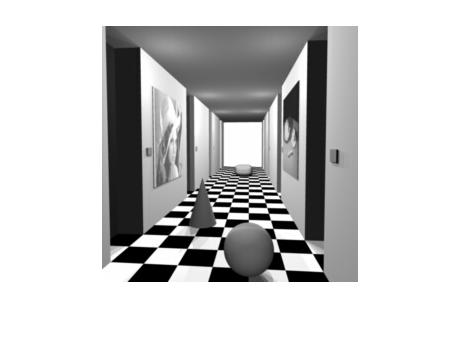

corridorL = imread('images/corridorl.jpg');
corridorL = rgb2gray(corridorL);
imshow(corridorL);

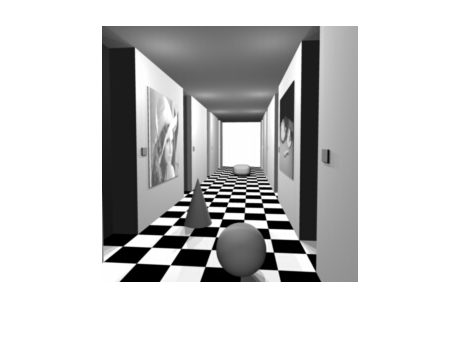


corridorR = imread('images/corridorr.jpg');
corridorR = rgb2gray(corridorR);
imshow(corridorR);

c) Run your algorithm on the two images to obtain a disparity map D, and see the results via

>> imshow(-D,[-15 15]);

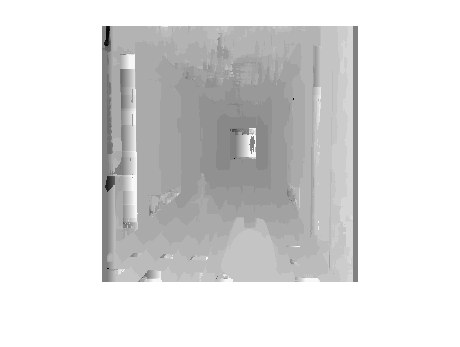

tic

disparityMap = getDisparityMap(corridorL, corridorR, 11, 11);
% not sure why but disparity map gray level is already inverted
imshow(disparityMap, [-15, 15]);


toc % confirm that using FFT is faster than conv

Elapsed time is 42.243345 seconds.


The results should show the nearer points as bright and the further points as dark. The expected quality of the image should be similar to `corridor_disp.jpg’ which you can view for reference.

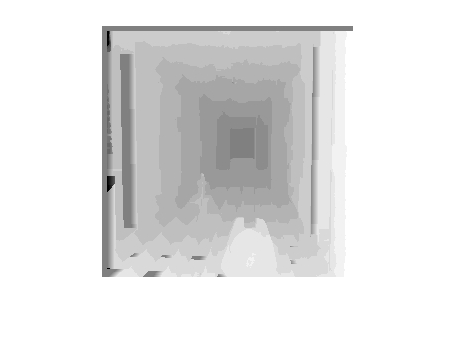

reference = imread('images/corridor_disp.jpg');
imshow(reference);

Comment on how the quality of the disparities computed varies with the corresponding local image structure.

How disparity quality varies with local image structure: 

It seems that the quality depends on local contrast within the image. For example, at the edges of walls for openings in the corridor, there are different bands of disparity. Also,at the end of the corridor, there is a patch ofdisparity (close to the right wall, ceiling and floor) that shows that the wall is very close, when in fact it is at the further point in 3D. This has probably got to do with the fact that sum-of-squares difference is used to compute disparity, and whenever there is high contrast, it leads to bigger disparity where there should not be.

d) Rerun your algorithm on the real images of ‘triclops-i2l.jpg’ and triclops-i2r.jpg’. Again you may refer to ‘triclops-id.jpg’ for expected quality. How does the image structure of the stereo images affect the accuracy of the estimated disparities?

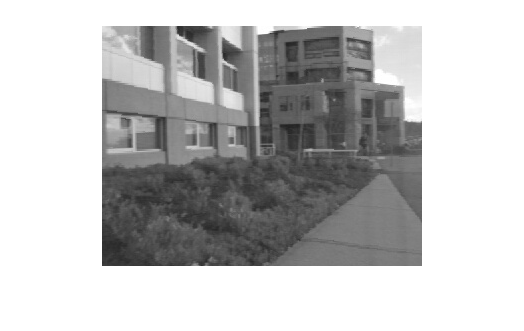

triclopsL = imread('images/triclops-i2l.jpg');
triclopsL = rgb2gray(triclopsL);
imshow(triclopsL);

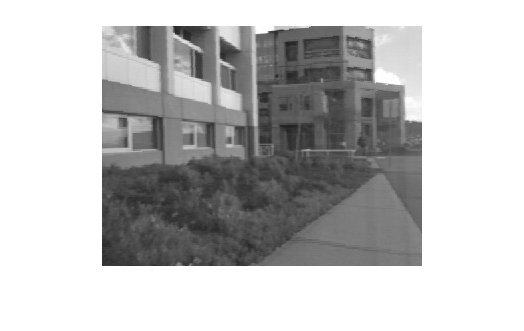


triclopsR = imread('images/triclops-i2r.jpg');
triclopsR = rgb2gray(triclopsR);
imshow(triclopsR);

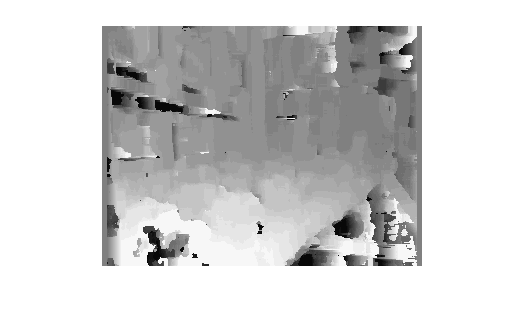


disparityMap = getDisparityMap(triclopsL , triclopsR, 11, 11);
% not sure why but disparity map gray level is already inverted
imshow(disparityMap, [-15, 15]);

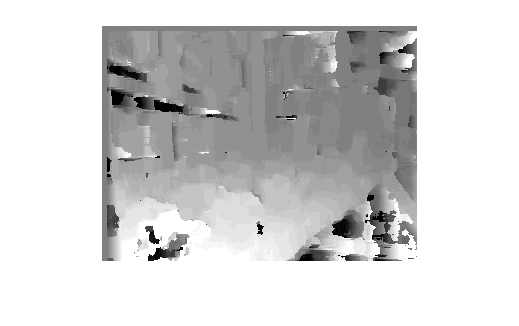


reference = imread('images/triclops-id.jpg');
imshow(reference);

How image structure affects accuracy of estimated disparities: This is the same problem as the one earlier, except disparity is more obviously affected where contrast is low. Parts of the road is smooth / even in both images, leading to a lowerdisparity based on SSD computation, which in turn make it seem as though these parts of the road is further away when they are not.